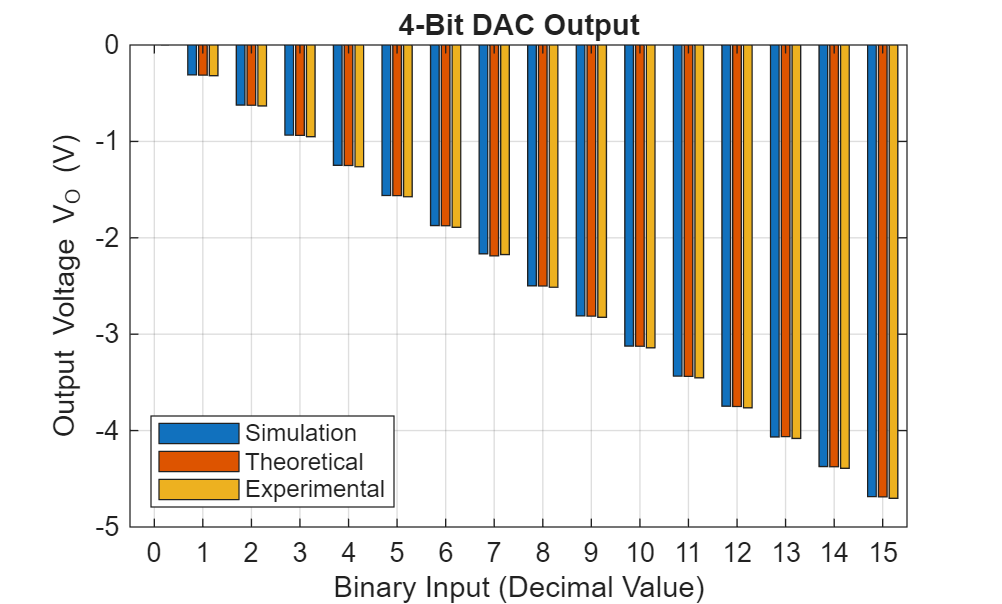

% Input values
input = 0:15;

% Output voltages
simulation = [0, -0.310, -0.623, -0.935, -1.248, -1.561, ...
              -1.873, -2.166, -2.498, -2.810, -3.123, -3.435, ...
              -3.747, -4.066, -4.373, -4.685];

theoretical = [0, -0.3125, -0.625, -0.9375, -1.25, -1.5625, ...
               -1.875, -2.1875, -2.5, -2.8125, -3.125, -3.4375, ...
               -3.75, -4.0625, -4.375, -4.6875];

experimental = [-0.001, -0.318, -0.632, -0.951, -1.263, -1.574, ...
                -1.891, -2.174, -2.513, -2.825, -3.141, -3.452, ...
                -3.764, -4.081, -4.391, -4.702];

% Combine data into a matrix
data = [simulation; theoretical; experimental]';

% Create bar plot
figure;
bar(input, data);

% Labels
xlabel('Binary Input (Decimal Value)')
ylabel('Output Voltage V_O (V)')
title('4-Bit DAC Output')

% Legend
legend('Simulation', 'Theoretical', 'Experimental', ...
       'Location', 'southwest');

% X-axis
xlim([-0.5 15.5])
xticks(0:1:15)

% Grid
grid on

exportgraphics(gcf, 'DAC_plot.jpg', 'Resolution', 300)